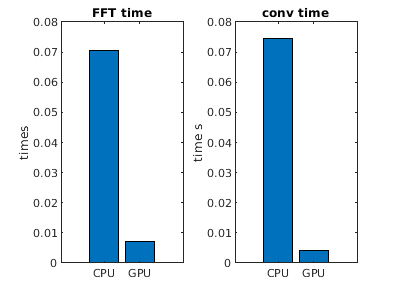

clear
% gen random data 
x = rand(1, 100000);

% using CPU computing the FFT&conv
tic;
y_fft_cpu = fft(x);
t_cpu_fft = toc;

h_conv_cpu = rand(1, 1000);
tic;
y_conv_cpu = conv(x, h_conv_cpu);
t_cpu_conv = toc;

% using GPU computing the FFT&conv
x_gpu = gpuArray(x);
h_conv_gpu = gpuArray(h_conv_cpu);

tic;
y_fft_gpu = fft(x_gpu);
wait(gpuDevice);
t_gpu_fft = toc;

tic;
y_conv_gpu = conv(x_gpu, h_conv_gpu);
wait(gpuDevice);
t_gpu_conv = toc;

% plot
figure;

% plot FFT time
subplot(1,2,1);
bar([t_cpu_fft, t_gpu_fft]);
ylabel('time�s	');
xticklabels({'CPU', 'GPU'});
title('FFT time');

% plot conv time
subplot(1,2,2);
bar([t_cpu_conv, t_gpu_conv]);
ylabel('time �s	');
xticklabels({'CPU', 'GPU'});
title('conv time');